format long
syms x
p_sym = (1/36)*x^3 + (5/18)*x^2 - x + (25/36);
lambda_sym = solve(p_sym, x);
l_1 = double(lambda_sym(1))

l_1 =      1


l_2 = double(lambda_sym(2))

l_2 =  -12.933034373659252


l_3 = double(lambda_sym(3))

l_3 =    1.933034373659253


r_W =    1.000000000000000
   0.998797983079708
   0.996474442955637
   0.991982961313107
   0.983300756279177
   0.966517970589153
   0.934073487331150
   0.871393160918610
   0.749764670006453
   0.520669909726703


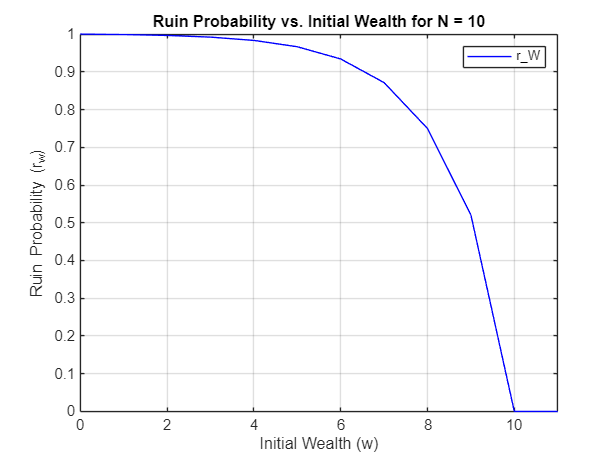

r_W =    1.000000000000000
   0.999999999999996
   0.999999999999987
   0.999999999999972
   0.999999999999941
   0.999999999999881
   0.999999999999766
   0.999999999999544
   0.999999999999114
   0.999999999998283


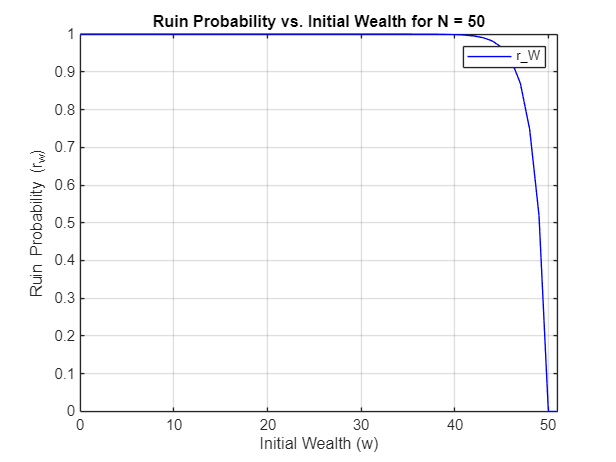

r_W =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


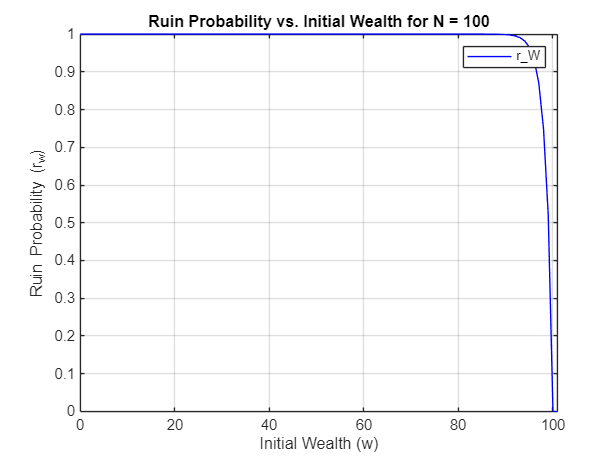


N_values = [10, 50, 100]; 
n = length(N_values);

for i = 1:n
    N = N_values(i);
    % Solve for coefficients
    syms c_1 c_2 c_3;
    [c_1, c_2, c_3] = solve( ...
    c_1 + c_2 + c_3 == 1, ...
    ((c_1)*(l_1)^(N)) + ((c_2)*(l_2)^(N)) + ((c_3)*(l_3)^(N)) == 0, ...
    ((c_1)*(l_1)^(N+1)) + ((c_2)*(l_2)^(N+1)) + ((c_3)*(l_3)^(N+1)) == 0);

    C1 = c_1;
    C2 = c_2;
    C3 = c_3;

    r_W = zeros(1, N+2);
    
    for W = 1:N+2
    r_W(W) = ((C1)*(l_1)^(W-1)) + ((C2)*(l_2)^(W-1)) + ((C3)*(l_3)^(W-1));
    end

    r_W = double(r_W)'

    figure;
    plot(0:N+1, r_W, 'b', 'DisplayName', 'r\_W');
    xlabel('Initial Wealth (w)');
    ylabel('Ruin Probability (r_w)');
    legend;
    title(['Ruin Probability vs. Initial Wealth for N = ', num2str(N)]);
    grid on;
    xlim([0 N+1])
    ylim([0.000 1.000])

end